# Presentation on Matrix and Vector Operation

## 1. Creating  Vector and Matrix

## 2. Builtin Matlab functions to create Matrix and Vectors

## 3. Operations on Matrix and vector

## 4. Using Matrix and Vectors in Image

# Creating Vector

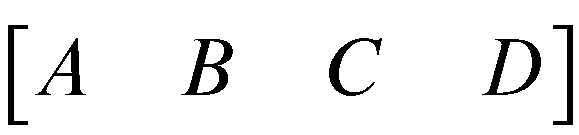

V = [1 2 3 4]

V =      1     2     3     4



[1, 2, 3, 4]

ans =      1     2     3     4


ones(1,20)*6

ans =      6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6


zeros(1,4)

ans =      0     0     0     0


# Creating Matrix

#  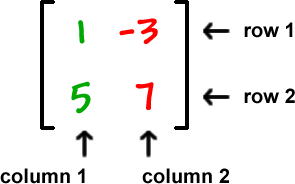

M = [1,-3 ; 5,7]

M =      1    -3
     5     7


[1 -3 ; 5 7]

ans =      1    -3
     5     7


rand(3,5)

ans =     0.2467    0.9137    0.1489    0.2057    0.8825
    0.7844    0.5583    0.8997    0.8997    0.2850
    0.8828    0.5989    0.4504    0.7626    0.6732


floor(rand(4,5)*90)

ans =     59    64    35    54    64
    11    25    44    51    79
    36    80    62    29    64
    24    74    75    41     1


min(min(floor(rand(4,5)*90)))

ans = 10

matrix = magic(5)

matrix =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


## Vector from Matrix

vector = matrix(1,:)

vector =     17    24     1     8    15


## Matrix from Vector

matrix = [vector; 2*vector; 3+vector]

matrix =     17    24     1     8    15
    34    48     2    16    30
    20    27     4    11    18


# Operations on Matrix and Vector

## 1. Addition & Subtraction

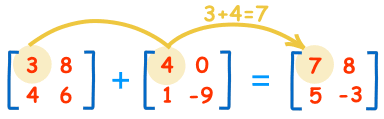

a = ones(4,4)

a =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


b = 2*ones(4,4)

b =      2     2     2     2
     2     2     2     2
     2     2     2     2
     2     2     2     2


c = a - b

c =     -1    -1    -1    -1
    -1    -1    -1    -1
    -1    -1    -1    -1
    -1    -1    -1    -1


a + 4 + b

ans =      7     7     7     7
     7     7     7     7
     7     7     7     7
     7     7     7     7


## 2. Multiplication

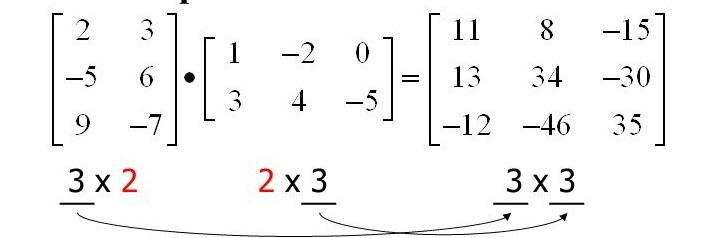

[2 3; -5 6; 9 -7] * [1 -2 0; 3 4 -5]

ans =     11     8   -15
    13    34   -30
   -12   -46    35


u = 2*ones(4,4)

u =      2     2     2     2
     2     2     2     2
     2     2     2     2
     2     2     2     2


v = 3 + zeros(4,4)

v =      3     3     3     3
     3     3     3     3
     3     3     3     3
     3     3     3     3


w = u.*v

w =      6     6     6     6
     6     6     6     6
     6     6     6     6
     6     6     6     6


w.*2

ans =     12    12    12    12
    12    12    12    12
    12    12    12    12
    12    12    12    12


## 3. Inverse

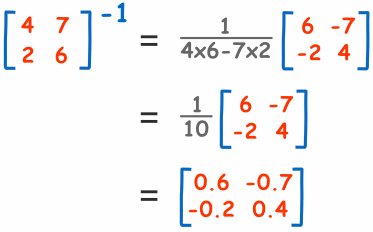

x = [4 7 ; 2 6]

x =      4     7
     2     6


inv(x)

ans =     0.6000   -0.7000
   -0.2000    0.4000


inv(x)*x

ans =     1.0000    0.0000
         0    1.0000


## 4. Division

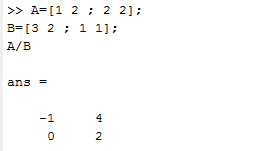

A = [1 2; 2 2]

A =      1     2
     2     2


B = [3 2; 1 1]

B =      3     2
     1     1


A/B

ans =     -1     4
     0     2


A*inv(B)

ans =    -1.0000    4.0000
         0    2.0000


A/2

ans =     0.5000    1.0000
    1.0000    1.0000


## 5. Transpose

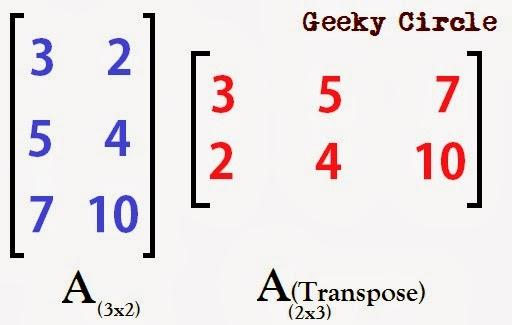

[3 2; 5 4; 7 10]

ans =      3     2
     5     4
     7    10


[3 2; 5 4; 7 10]'

ans =      3     5     7
     2     4    10


p = ones(3,2)

p =      1     1
     1     1
     1     1


q = 2*ones(3,4)

q =      2     2     2     2
     2     2     2     2
     2     2     2     2


p'

ans =      1     1     1
     1     1     1


p'*q

ans =      6     6     6     6
     6     6     6     6


## 6. Conjugate

a = 1 + 3i

a =    1.0000 + 3.0000i


a'

ans =    1.0000 - 3.0000i


[a a]

ans =    1.0000 + 3.0000i   1.0000 + 3.0000i


[a a]'

ans =    1.0000 - 3.0000i
   1.0000 - 3.0000i


[j j j; j j j]'

ans =    1.0000 - 3.0000i   1.0000 - 3.0000i
   1.0000 - 3.0000i   1.0000 - 3.0000i
   1.0000 - 3.0000i   1.0000 - 3.0000i


## Distance calculation: Euclidean

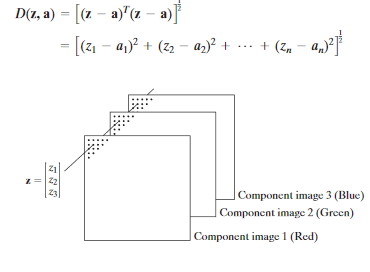

z = [1 1 1]

z =      1     1     1


a = [ 1 1 1]

a =      1     1     1


d = sqrt(sum((z-a).^2))

d = 0

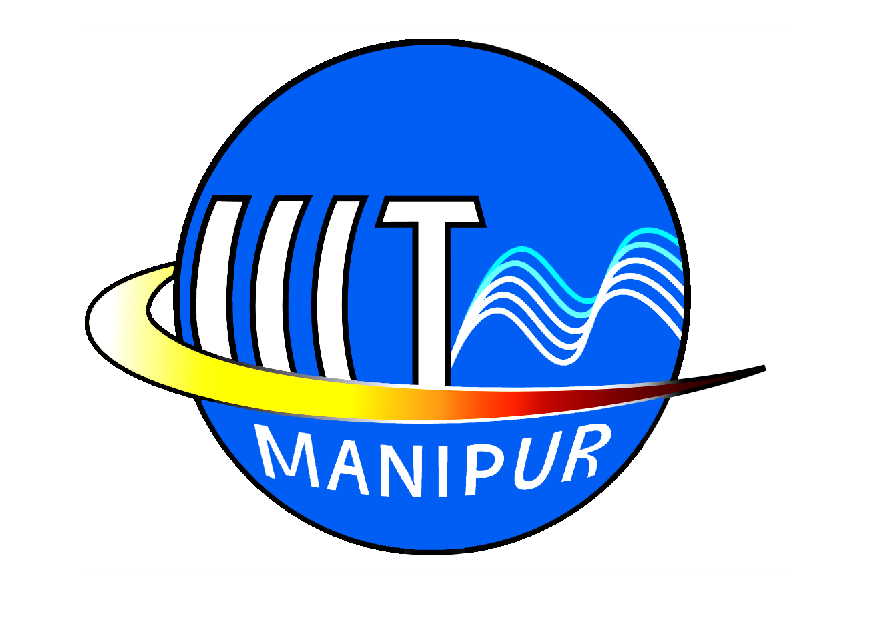

test = imread('logo.png');
imshow(test)

size(test)

ans =          812        1058           3


test = imresize(test, 0.2);
size(test)

ans =    163   212     3


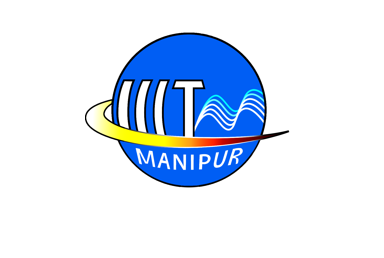

imshow(test)

test = rgb2gray(test);
size(test)

ans =    163   212


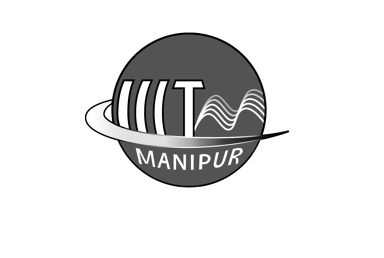

imshow(test)

temp = test;
d = sqrt(sum(sum((test-temp).^2)))

d = 0